# Lab02 - Assignment

#### Student Nr: 20190808064

#### Name, Lastname:  Ali Çolak

## Assignment Description

Your task is to compare Employment to population ratio above age 15, since 1991 for  two countries that you selected with a figure.

[https://data.worldbank.org/](https://data.worldbank.org/) is a webside that you can obtain open source data about countries, economies and etc. 

#### How to Download Data

- Go to [https://data.worldbank.org/](https://data.worldbank.org/) website. Search for "Employment to population ratio, 15+, total (%) (modeled ILO estimate)". 

- On the right side, you can download the data with file formats. Download the data with .csv format. The file contains the data for all the countries. You should select Select two countries (you can select any country that have data between 1991 and 2020). 

## Code

#### Clear workspace

clear
clc

#### Task 1: Import Data

Load the .csv data and select the data for two countries.

Country 1:       ** Turkey**

Country 2:        Brazil

Turkey=readmatrix("API_SL.EMP.TOTL.SP.ZS_DS2_en_csv_v2_2056759.csv","Range",[248 36 248 65])

Turkey =    51.8100   50.7200   46.9400   49.4000   49.3900   49.4800   48.1600   48.2700   47.7400   45.6300   44.5300   43.2700   42.0000   40.9800   41.1300   41.1300   41.0800   41.3400   40.7800   42.6100   44.4900   44.7500   45.3000   45.1600   45.7500   46.1200   46.8500   47.1600   45.5400   43.3700


Brazil=readmatrix("API_SL.EMP.TOTL.SP.ZS_DS2_en_csv_v2_2056759.csv","Range",[33 36 33 65])

Brazil =    58.1200   58.4900   59.1400   59.4000   59.6800   57.8800   57.9300   57.3200   57.3400   57.7500   58.1500   58.9400   58.5500   59.7500   60.0200   60.2700   60.1800   60.8200   60.2400   59.7300   59.1900   59.6700   59.7000   59.6400   58.6500   56.3900   55.8400   56.1500   56.7600   51.1400


#### Task 2: Plot data for two countries between 1991 and 2020. You are free to use any line style or color. Don't forget to add legends in the figure!

t=1991:2020

t =         1991        1992        1993        1994        1995        1996        1997        1998        1999        2000        2001        2002        2003        2004        2005        2006        2007        2008        2009        2010        2011        2012        2013        2014        2015        2016        2017        2018        2019        2020


plot(t,Turkey,"red","LineWidth",4)
hold on
plot(t,Brazil,"yellow","LineWidth",4)
legend('Turkey','Brazil')
title("Employment to population ratio, 15+, total (%) (modeled ILO estimate)")
ylabel("Employment to population ratio")
xlabel("Years")


#### Task 3: Find max and mean values for those 2 countries

[maxTurkey,maxTurkeyIndex]=max(Turkey)

maxTurkey = 51.8100

maxTurkeyIndex = 1

meanTurkey=mean(Turkey)

meanTurkey = 45.3627

[maxBrazil,maxBrazilIndex]=max(Brazil)

maxBrazil = 60.8200

maxBrazilIndex = 18

meanBrazil=mean(Brazil)

meanBrazil = 58.4277

#### Task 4: Mark max values for each country in the figure

plot(t(maxTurkeyIndex),maxTurkey,"o","MarkerSize",8)
plot(t(maxBrazilIndex),maxBrazil,"o","MarkerSize",8)


#### Task 5: Draw a line for each country that represents mean (average) of the employment data through x axis. (Matlab command is *yline*)

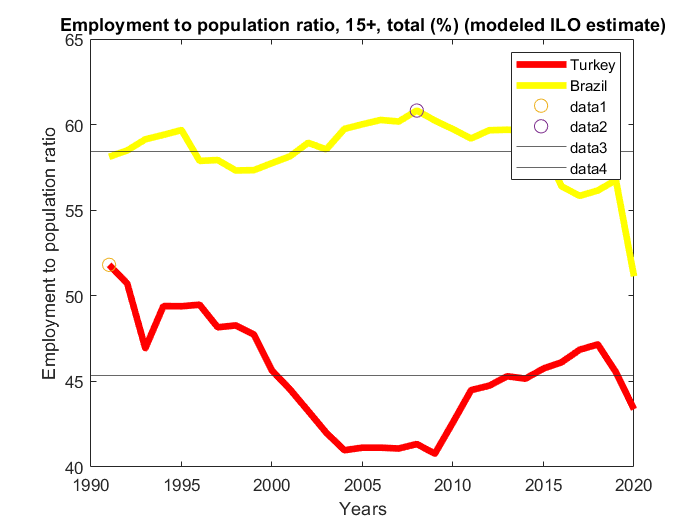

yline(meanTurkey)
yline(meanBrazil)

# Finally, export this file as pdf by clicking Save->Export to PDF